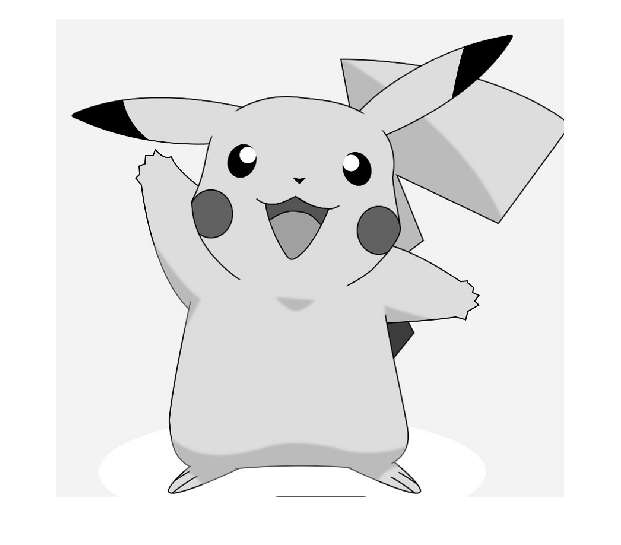


close all; clear all; clc;
IMG = rgb2gray(imread('2.bmp')); % transfer to grayscalce pic
figure; 
imshow(IMG);            

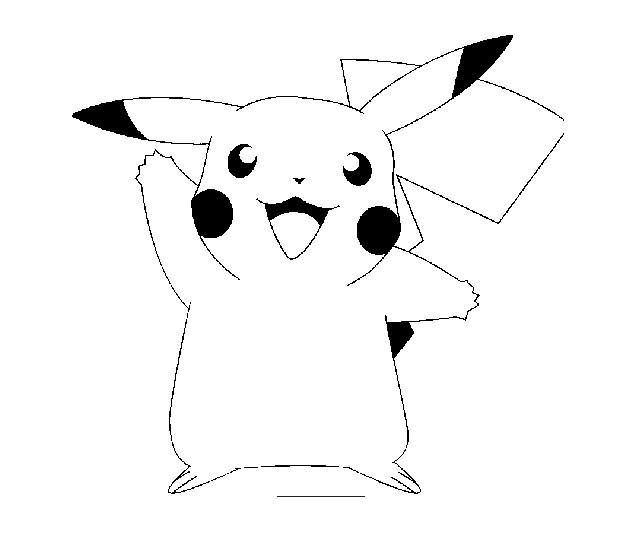


% IMG=imrotate(IMG,-90);
IMG = im2bw(IMG,0.5);
figure(2);
imshow(IMG);

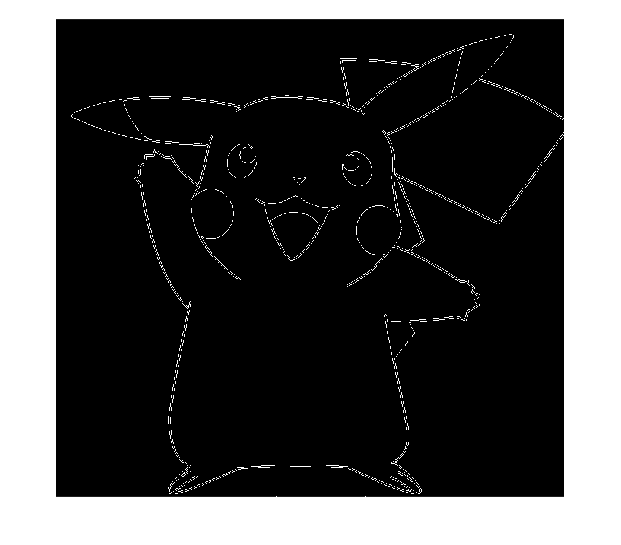


IMG = IMG - imerode(IMG,[0 1 0 ; 1 1 1 ; 0 1 0]);
%IMG=im2bw(IMG,0.5);
figure(3); 
imshow(IMG);

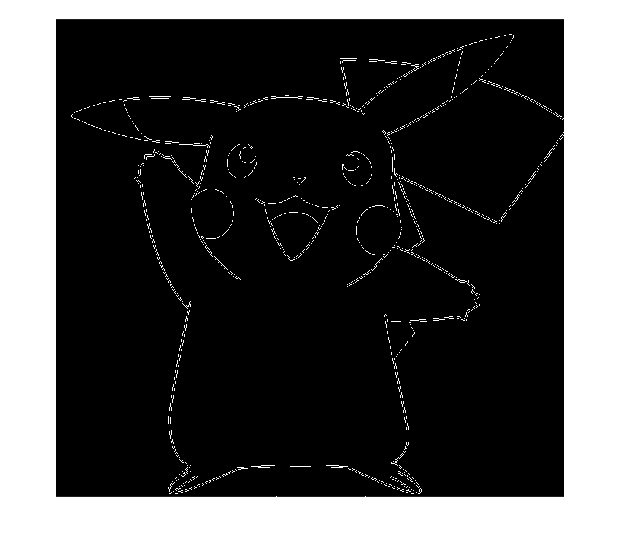

IMG = bwmorph(IMG,'thin',Inf);
% IMG1 = bwmorph(IMG,'botha');
% IMG1 = bwmorph(IMG1,'thin',Inf);
% IMG=IMG-IMG1;
figure(4); 
imshow(IMG);

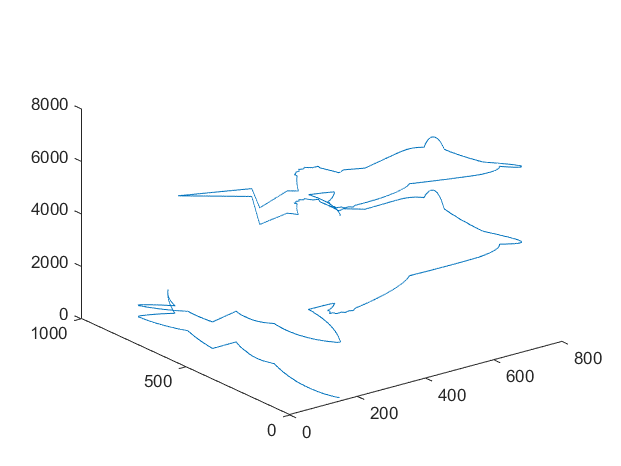

C1=contour_get(IMG);

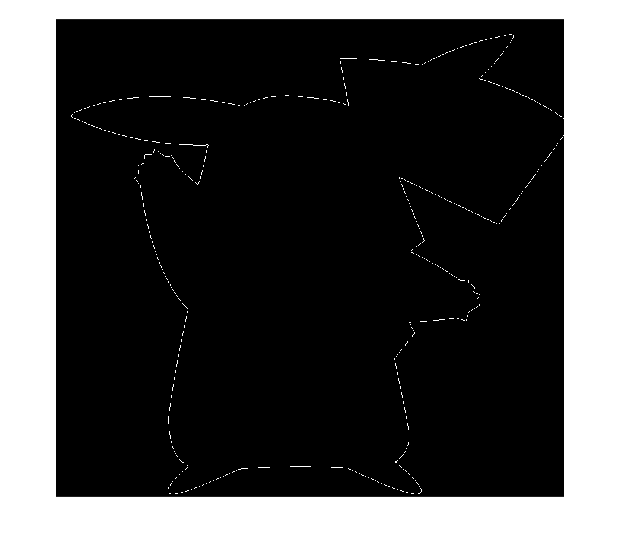

figure
imshow(C1)

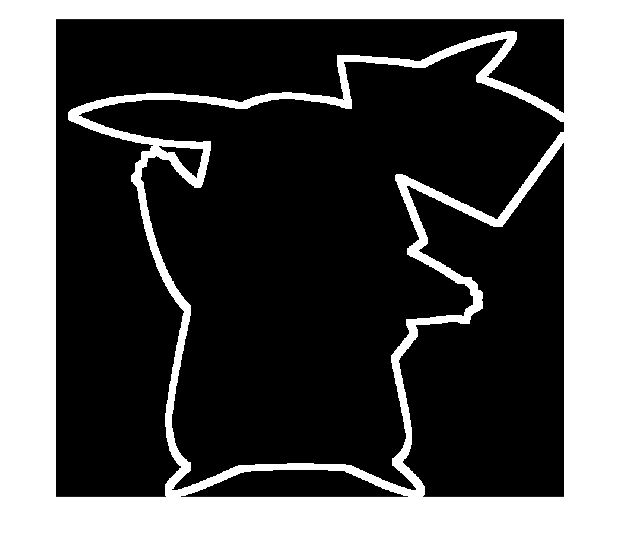

% se90 = strel('line',3,90);
% se0 = strel('line',3,0);
% Csdil= imdilate(C1,[se90 se0]);
se = ones(11,11);
Csdil= imdilate(C1,se);
figure
imshow(Csdil)

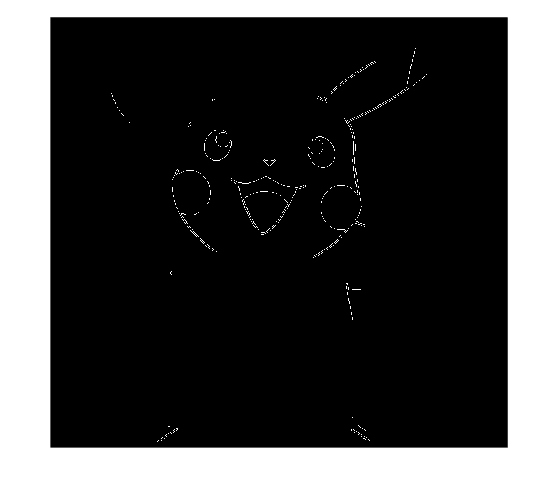

IMG1=linedelete(IMG,Csdil);
imshow(IMG1)

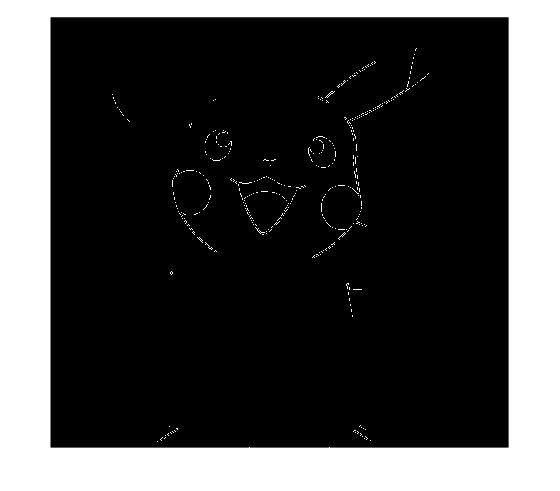

IMG1 = bwmorph(IMG1,'thin',Inf);
imshow(IMG1)

% close all; clear all; clc;
% IMG = rgb2gray(imread('2.bmp'));
% [ ~ , threshold]  = edge ( IMG , 'sobel' );
% fudgefactor = 0.5;
% Bws = edge ( IMG , 'sobel' , threshold*fudgefactor ) ;
% figure(5); 
% imshow(Bws)